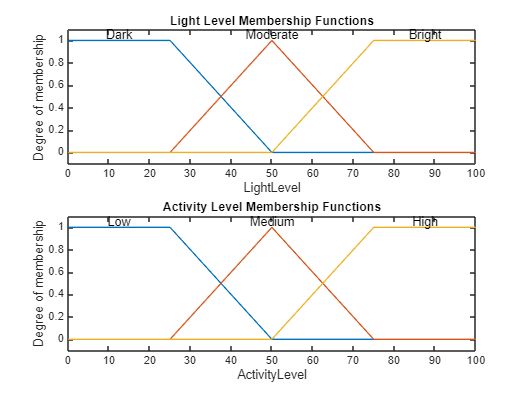

%% Fuzzy Logic Controller for Light Level and Activity Level
% Create Mamdani FIS object
fis = mamfis('Name', 'LightActivityController', ...
    'AndMethod', 'min', ...
    'OrMethod', 'max', ...
    'ImplicationMethod', 'min', ...
    'AggregationMethod', 'max', ...
    'DefuzzificationMethod', 'centroid');

%% Input Variables
% Input 1: Light Level (0 to 100)
fis = addInput(fis, [0 100], 'Name', 'LightLevel');
fis = addMF(fis, 'LightLevel', 'trapmf', [0 0 25 50], 'Name', 'Dark');
fis = addMF(fis, 'LightLevel', 'trimf', [25 50 75], 'Name', 'Moderate');
fis = addMF(fis, 'LightLevel', 'trapmf', [50 75 100 100], 'Name', 'Bright');

% Input 2: Activity Level (0 to 100)
fis = addInput(fis, [0 100], 'Name', 'ActivityLevel');
fis = addMF(fis, 'ActivityLevel', 'trapmf', [0 0 25 50], 'Name', 'Low');
fis = addMF(fis, 'ActivityLevel', 'trimf', [25 50 75], 'Name', 'Medium');
fis = addMF(fis, 'ActivityLevel', 'trapmf', [50 75 100 100], 'Name', 'High');

%% Output Variable
% Output: Light Intensity (0 to 100)
fis = addOutput(fis, [0 100], 'Name', 'LightIntensity');
fis = addMF(fis, 'LightIntensity', 'trapmf', [0 0 25 50], 'Name', 'Low');
fis = addMF(fis, 'LightIntensity', 'trimf', [25 50 75], 'Name', 'Medium');
fis = addMF(fis, 'LightIntensity', 'trapmf', [50 75 100 100], 'Name', 'High');

%% Rule Base
rules = [
    "If LightLevel is Dark and ActivityLevel is Low then LightIntensity is Low";
    "If LightLevel is Dark and ActivityLevel is Medium then LightIntensity is Medium";
    "If LightLevel is Dark and ActivityLevel is High then LightIntensity is High";
    "If LightLevel is Moderate and ActivityLevel is Low then LightIntensity is Low";
    "If LightLevel is Moderate and ActivityLevel is Medium then LightIntensity is Medium";
    "If LightLevel is Moderate and ActivityLevel is High then LightIntensity is High";
    "If LightLevel is Bright and ActivityLevel is Low then LightIntensity is Low";
    "If LightLevel is Bright and ActivityLevel is Medium then LightIntensity is Medium";
    "If LightLevel is Bright and ActivityLevel is High then LightIntensity is High";
];

fis = addRule(fis, rules);

%% Visualization
% Membership functions for inputs
figure('Name','Membership Functions for Inputs');
subplot(2,1,1); plotmf(fis,'input',1); title('Light Level Membership Functions');
subplot(2,1,2); plotmf(fis,'input',2); title('Activity Level Membership Functions');

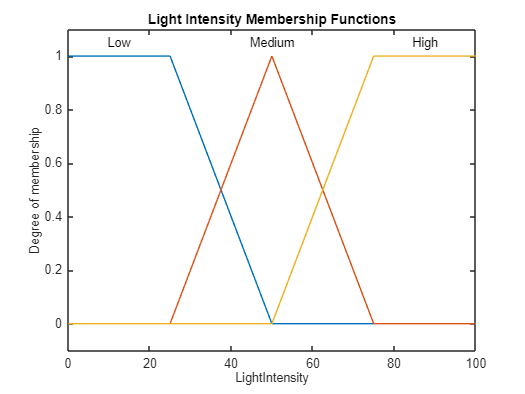


% Membership functions for output
figure('Name','Membership Functions for Output');
plotmf(fis,'output',1); title('Light Intensity Membership Functions');

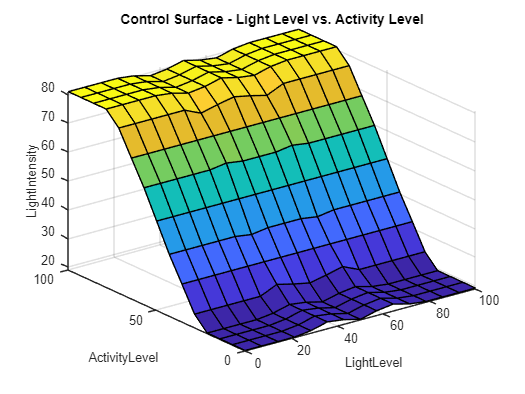


% Control surface plot
figure('Name','Control Surface');
gensurf(fis);
title('Control Surface - Light Level vs. Activity Level');


%% Simulation
% Test sample input (e.g., Light Level = 30%, Activity Level = 70%)
inputValues = [30, 70];
output = evalfis(fis, inputValues);
fprintf('For Light Level=%.2f%% and Activity Level=%.2f%%:\nLight Intensity: %.2f%%\n\n',...
        inputValues(1), inputValues(2), output);

For Light Level=30.00% and Activity Level=70.00%:
Light Intensity: 74.51%




% Example inputs
testInputs = [
    [10, 20]; % Dark with low activity
    [50, 60]; % Moderate light with medium activity
    [80, 90]; % Bright light with high activity
];

% Evaluate system for each input
for i = 1:size(testInputs,1)
    output = evalfis(fis, testInputs(i,:));
    fprintf('For Light Level=%.2f%% and Activity Level=%.2f%%:\nLight Intensity: %.2f%%\n\n',...
            testInputs(i,1), testInputs(i,2), output);
end

For Light Level=10.00% and Activity Level=20.00%:
Light Intensity: 19.18%

For Light Level=50.00% and Activity Level=60.00%:
Light Intensity: 62.90%

For Light Level=80.00% and Activity Level=90.00%:
Light Intensity: 80.82%



fuzzyLogicDesigner(fis);